clc % clear command window
clear % clear MATLAB workspace

**Set up robot control system**

**Load a map of Olin Oval test track (to be built into a Binary Occupancy Grid)**

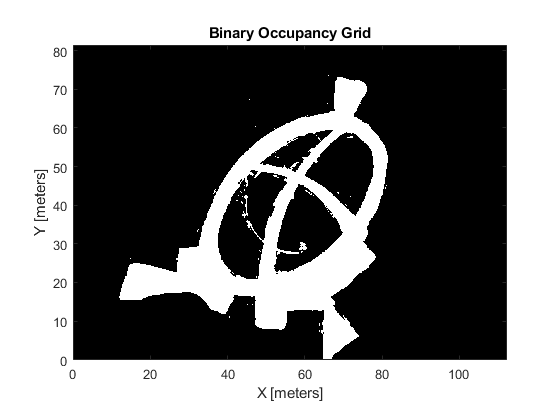

img = imread('OlinOvalMap.png'); % load Oval Image
grayimage = im2gray(img); % convert to grayscale
bwimage = grayimage < 0.5; %convert to black and white
MapofOval = binaryOccupancyMap(bwimage,10); % convert to binary occupacy map in meter 
show(MapofOval); % show map

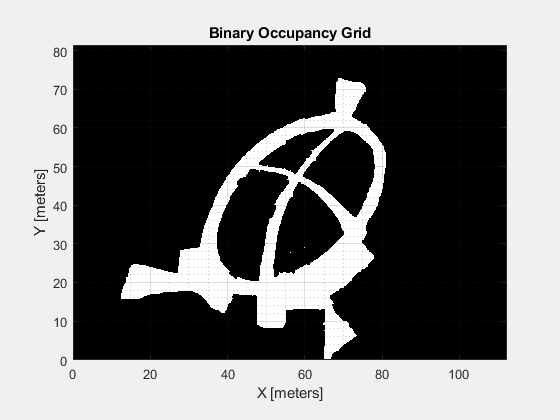

% Inflate the map with the robot rover size, so the robot can be treated as
% a point. Assume robot rover 0.25 m long(bow to stern)
MapOfOvalInflated = copy(MapofOval); % make a copy so I ont lose original data
inflate(MapOfOvalInflated, 0.25); %dilate map to accomodate the robot body size
% create a free floating figure for the map to deal with the livescript
% update issue
ovalTrack = figure('name','OvalTrackMap','NumberTitle','off','Visible','on');
figure(ovalTrack)
    show(MapOfOvalInflated); %show map in a new figure window
    grid on;
    grid minor;

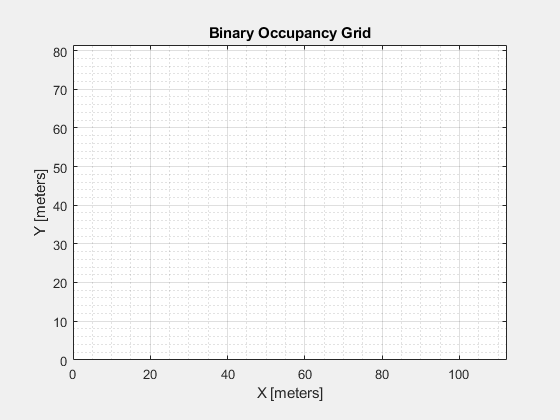

% Create an empty map of the same dimensions as the test track map
[mapdimx, mapdimy] = size(bwimage); %find size of map
lidarMap = binaryOccupancyMap(mapdimx,mapdimy,10,'grid'); %make map of the same size

%create a free floating figure for the map to deal with the livescript
%update problem
roverLidarScan = figure('name','RoverLidarScan','NumberTitle','off','Visible','on');
figure(roverLidarScan)
    show(lidarMap);
    grid on;
    grid minor;

Create a diffrential drive robot rover (this model takes robot vehicle speed and heading for inputs)

 diffDriveRover = differentialDriveKinematics("VehicleInputs","VehicleSpeedHeadingRate");
 

Create a pure pursuit robot controller(this controller generates the robot speed and headign needed to follow a desired path, set desired linear velocity and max angular velocity in m/s and rad/s

 RoverController = controllerPurePursuit('DesiredLinearVelocity',2,'MaxAngularVelocity',3);
 

Create 360 degree LIDAR range sensor for your rover:

- Create a sensor with a max range of 40 m. This sensor simulates range readings based on a given pose and map. The Olin Oval map is used with this range sensor to simulate collecting senosr readings in an unknown environment. 

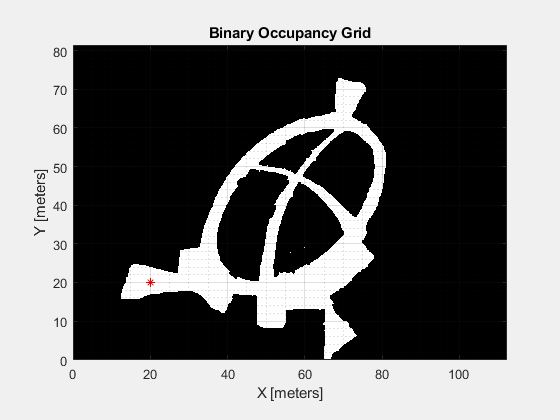

 lidar = rangeSensor;
 lidar.Range = [0.5,40]; %sets minimum and maximum range of sensors
 testPose = [20 20 pi/2]; % set an initial test pose for lidar
 
 % Plot the test spot for lidar scan on the reference Olin Oval Map
 figure(ovalTrack) %designate free floating OvalTrackMap to draw on 
 hold on
 plot(20,20,'r*'); % plot robot position in oval
 hold off

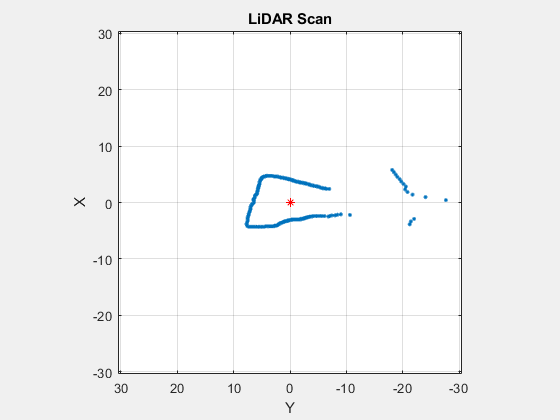

% Generate a lidar test scan from test position
[ranges,angles] = lidar(testPose, MapOfOvalInflated);
scan = lidarScan(ranges,angles);

% Visualize the test lidar scan data in robot coordinate system. 
% create a new free-standing figure to display the local lidar data,rover
% at center
    localLidarPlot = figure('Name','locallidarMap','NumberTitle','off','Visible','on');
    figure(localLidarPlot)
    plot(scan)
    hold on;
    plot(0,0,'r*'); % plot robot position
    hold off;

Create a test path to drive through the map for gathering range sensor readings

path = [20 20;30 20;38 20;35 25;38 40;45 50;58 60]; %path waypoints

% Plot the path on the reference map figure.
figure(ovalTrack)
hold on
plot(path(:,1),path(:,2),'o-'); % plot path on it
hold off

Use this test path as the set of waypoints the pure pursuit controller will follow:

Rover.Controller.Waypoints = path; % set rover waypoints

Set the initial pose and final goalWayPoint location based on the path. Create global variables for storing the current pose and an index for tracking the iterations.

initRoverPose = [path(1,1) path(1,2), pi/2]; % store initial location and oreintation of
goalWayPoint = [path(end,1) path(end,2)]'; % path end waypoint
sampleTime = 0.10; %sample time[s]
t = 0:sampleTime:100; %time array
robotPoses = zeros(3,numel(t)); %pose matrix
robotPoses(:,1) = initRoverPose'; %store robotPoses
r = rateControl(1/sampleTime); % reset control loop rate
reset(r); % reset loop time to zero

Ready to run robot, ask operator if they are set and suggest they move plots to a visable position


runRover = input('Ready to run Rover? Please arrange your data plot figures for clear visable')
clc

## Run Robot Control Loop

controlIndex = 1; % create a robot loop control
while (controlIndex < numel(t)) % loop for the number of elements in t
    position = robotPoses(:,controlIndex)'; % rover current position
    roverLocation = position(1:2); %current rover X and Y from position
    
    % End loop if rover has reached goal waypoint within tolerance of 1.0 m
    dist = norm(goalWayPoint'-roverLocation);
    if (dist < 1.0) % robot reaches end goal
        disp('Goal position reached')
        break; % stop control loop
    end
    
   % SENSE: collect data from robot lidar 
    % function  [ranges, angles] = SENSE(position, mapOfTrack, blankLidarMap, fig_lidarMap, fig_localLidarPlot, lidar)
    [ranges, angles] = SENSE(position, MapOfOvalInflated, lidarMap ,roverLidarScan, localLidarPlot, lidar);  
    
    % THINK: compute what robot should do next
    % function [roverX,roverY, poses] = THINK(poses,diffDrive, ppControl,sampleTime, loopIndex)
    [roverX, roverY, robotPoses] = THINK(robotPoses,diffDriveRover,RoverController,sampleTime, controlIndex);
    
    %ACT: command robot actuators
    ACT(roverX,roverY,ovalTrack);
    
    controlIndex = controlIndex + 1; % increment contro loop index
    waitfor(r); % wait for loop cycle to complete
end

beep % give audio indication waypoint is reached

## Robot Functions(store the local functions here)

**In practice for modularity, readability and longitevity, your main robot control code should be as brief as possible and bulk of the work should be done by functions. Functions also well support team programming as each subteam can develop their functions independently from other subteams**

**Sense Function** (store all Sense related Local functions)

function [ranges,angles] = SENSE(position, mapOfTrack, blankLidarMap, fig_lidarMap, fig_localLidarPLot,lidar)
% SENSE scans the reference map using the range sensor and the current
% pose. This simulates normal range readings for driving in an unknown
% environment. Update the lidar map with the range readings. Inputs are
% rover position, mapOfTrack, lidarap, figure to plot global lidar, figure
% to plot outputs are lidar ranges and angles in local coordinate system.
    [ranges,angles] = lidar(position, mapOfTrack);
    scan = lidarScan(ranges,angles);
    validscan = removeInvalidData(scan, 'RangeLimits',[0,lidar.Range(2)]);
    insertRay(blankLidarMap,position,validScan,lidar.Range(2));
    
    figure(fig_lidarMap);
        hold on;
        show(blankLidarMap);
        grid on;
        grid minor;
        hold off;
     
    figure(fig_localLidarPLot);
    plot(scan);
    hold on;
    plot(0,0,'r*'); % plot robot position
    hold off;   
end

**Think Function **(store all Think related Local functions)

function [roverX,roverY,poses] = THINK(poses,diffDrive,ppControl,sampleTime,loopIndex)
% THINK gets control commands from pure pursuit controller to drive to the
% next waypoint. Calculate derivative of robot motion based on control
% commands. Inputs are rover poses, diffDrive dynamics, loop sampletime,
% loop index. Outputs are roverX, roverY, robot poses (position of robot)

    %Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = ppControl(poses(:,loopIndex));
    
    % Perform forward discrete integration step
    vel = derivation(diffDrive, poses(:,loopIndex),[vRef wRef]);
    
    poses(:,loopIndex + 1) = poses(:,loopIndex) + vel*sampleTime;
    
    % Update rover location and pose
    roverX = poses(1,loopIndex + 1);
    roverY = poses(2,loopIndex + 2);
    
    
end

**Act Function **(store all Act related Local functions)

function ACT(time)
% ACT Increment the robot pose based on the derivative. 
% Inpute are current X and Y positions of rover and figure to plot rover
% in. 
% There are no outputs
    figure(fig_testTrack)
    hold on
    plot(roverX, roverY, 'b*'); % plot the robot position in oval
    hold off
end
